clear; clear path; clc;
cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG


approximate zoh plant

riseTime = 0.022295; %seconds
Ts = riseTime/10;
Psz = Ps*exp(-Ts/2);

we now tune a contiunous pid on the continuous estimator of zoh plant

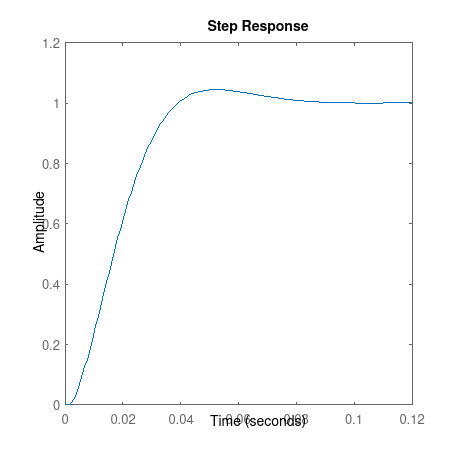

P = 10;
I = 0;
D = 60;
N = 120;
Csz = pidGen(P,I,D,N,1);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Csz*Psz/(1+Csz*Psz))

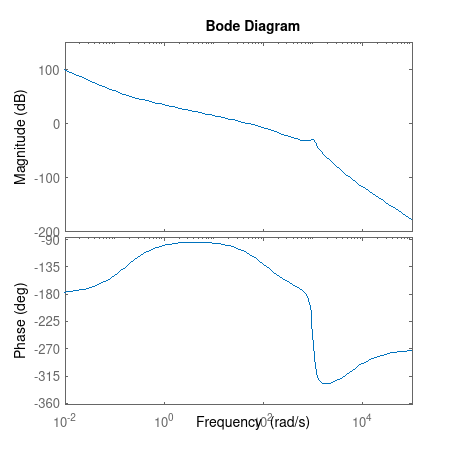


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Csz*Psz)

we will now fix the input gain saturation

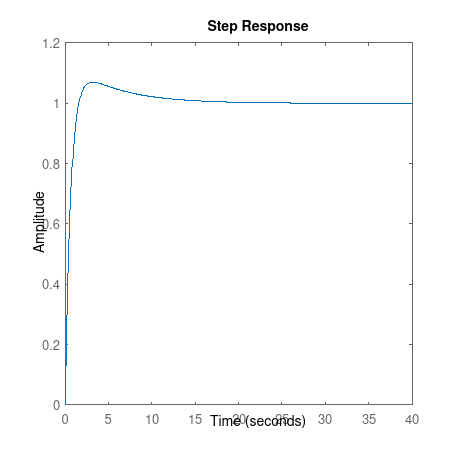

uMax = max(step(Csz/(1+Csz*Psz)));
Csz = pidGen(P,I,D,N,200/uMax);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Csz*Psz/(1+Csz*Psz))

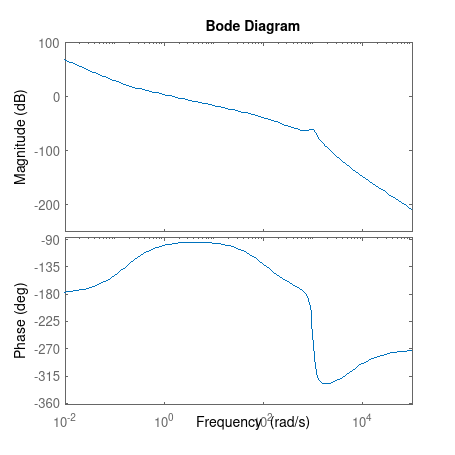


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Csz*Psz)

We will now get the actual discrete system

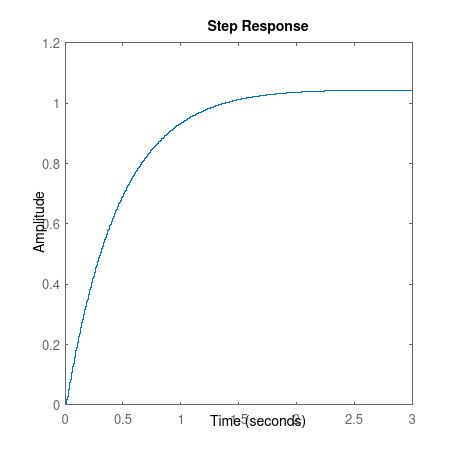

Pz = c2d(Ps,Ts);
Cz = c2d(Csz,Ts);

figure('Position',[0 0 1000 1000]); clf; hold on;
step(Cz*Pz/(1+Cz*Pz))

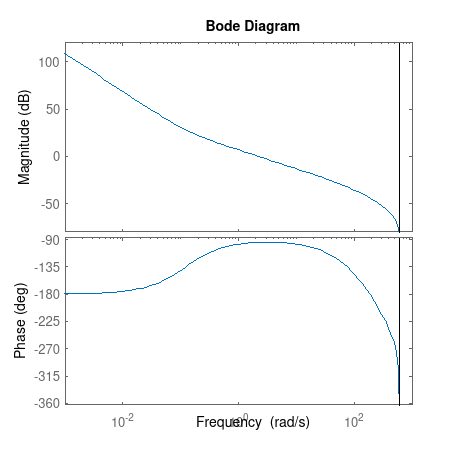


figure('Position',[0 0 1000 1000]); clf; hold on;
bode(Cz*Pz)

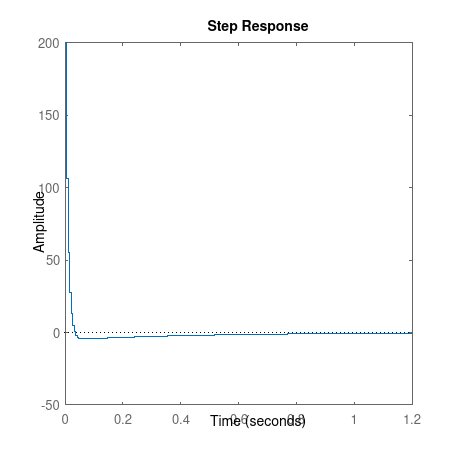


figure('Position',[0 0 1000 1000]); clf; hold on;
step(Cz/(1+Cz*Pz))